# Macro III: Problem Set 3

Deadline: Friday, 17/09/2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_03](https://github.com/btebaldi/Macro3/tree/master/PSet_02)

## Questao 2

## Item F

A arrecadação do governo pode ser escrita como:


$$G = \tau_y K_t^{\alpha}N_t^{1-\alpha} + \tau_n w_t N_t$$


Em termos per capta temos: 


$$g = \tau_y k_t^{\alpha} + \tau_n w_t$$


Se a arrecadação é constante, pelo teorema da função implicita temos:


$$\frac{d\tau_y}{d\tau_n} = \frac{-w}{k^\alpha}$$


substituindo a equacoes de w temos:


$$\frac{d\tau_y}{d\tau_n} = -\frac{(1-\tau_y)(1-\alpha)}{(1+\tau_n)}$$



$$\frac{d\tau_y}{d\tau_n} = -0.48$$


Utilizando o conceito de diferencial temos:


$$\Delta\tau_y = -0.48 \Delta\tau_n = (-0.48)*(-0.05) = 0.024$$


Logo é esperado que $\tau_y$ seja próximo de 0.024.

% Lipeza de variaveis
clearvars
clc


% Cria um processo de markov com as caracteristicas especificadas.
sigma = ((1-0.98^2)*0.621)^0.5;
mkv = MarkovProcess(0.98, sigma ,2,7,0);
mkv.AR.sigma2_y

ans = 0.6210

[chain,state] = MarkovSimulation(mkv.TransitionMatrix, 1000, mkv.StateVector, 3);

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

tau_y:0.000	tau_n:0.250
Inter:   1	r: -0.019167	Dem: -8.253269
Inter:   2	r: -0.049583	Dem: 61.290115
Inter:   3	r: -0.034375	Dem: 20.366287
Inter:   4	r: -0.026771	Dem: 6.357693
Inter:   5	r: -0.022969	Dem: 0.695067
Inter:   6	r: -0.021068	Dem: -3.167669
Inter:   7	r: -0.022018	Dem: -0.961379
Inter:   8	r: -0.022493	Dem: -0.000415
Inter:   9	r: -0.022731	Dem: 0.372352
Inter:  10	r: -0.022612	Dem: 0.159592
Inter:  11	r: -0.022553	Dem: 0.079587
Inter:  12	r: -0.022523	Dem: 0.039594
Inter:  13	r: -0.022508	Dem: 0.019590
Inter:  14	r: -0.022501	Dem: 0.009588
Inter:  15	r: -0.022497	Dem: 0.004586
Inter:  16	r: -0.022495	Dem: 0.002086
Inter:  17	r: -0.022494	Dem: 0.000835
Inter:  18	r: -0.022494	Dem: 0.000210
Inter:  19	r: -0.022494	Dem: -0.000102
Inter:  20	r: -0.022494	Dem: 0.000054
Inter:  21	r: -0.022494	Dem: -0.000024
Inter:  22	r: -0.022494	Dem: 0.000015
interest rate: -0.022494
wage rate: 1.749060


ans = 20×7 table
     Var1      Var2      Var3      Var4      Var5      Var6      Var7 
    ______    ______    ______    ______    ______    ______    ______

       100    16.079    16.079    16.079    16.079    16.079    20.496
    16.079    20.496    20.496    20.496    20.496    20.496    24.913
    20.496    24.913    24.913    24.913    24.913    24.913     29.33
    24.913    24.913    24.913    24.913    24.913     29.33    33.747
     29.33     29.33    33.747    33.747    33.747    33.747    38.164
    33.747    33.747    38.164    38.164    38.164    38.164    38.164
    38.164    38.164    38.164    38.164    38.164    38.164    38.164
     42.58     42.58     42.58    46.997     42.58     42.58     42.58
    46.997    46.997    46.997    

ans = 20×7 table
    Var1     Var2       Var3       Var4       Var5       Var6        Var7  
    ____    _______    _______    _______    _______    _______    ________

    0.01    0.84368    0.68737    0.58316    0.47895    0.37474     0.68737
    0.01    0.89579    0.73947    0.58316    0.47895    0.42684     0.68737
    0.01    0.94789    0.79158    0.63526    0.53105    0.42684     0.68737
    0.01       0.01       0.01       0.01       0.01    0.42684     0.73947
    0.01       0.01    0.89579    0.68737    0.53105    0.42684     0.73947
    0.01       0.01    0.89579    0.73947    0.58316    0.47895     0.37474
    0.01       0.01       0.01       0.01       0.01       0.01        0.01
    0.01       0.01       0.01    0.79158       0.01       0

ans = 20×7 table
     Lambda1      Lambda2      Lambda3       Lambda4       Lambda5       Lambda6       Lambda7  
    _________    _________    __________    __________    __________    __________    __________

    0.0048275    0.0073525     0.0090101     0.0085093     0.0058144     0.0024458    8.6144e-05
    0.0049136    0.0075242       0.00927     0.0088076     0.0060743     0.0026176    0.00017229
    0.0049997     0.083567       0.11239       0.10726      0.074169      0.031348     0.0012643
    0.0020709    0.0037203      0.000244    2.4428e-09     5.651e-05     0.0009166     0.0012078
    0.0020774    0.0039578     0.0055569     0.0059899     0.0048784     0.0029277      0.001226
     0.002084    0.0039695      0.053212      0.089363       0.10

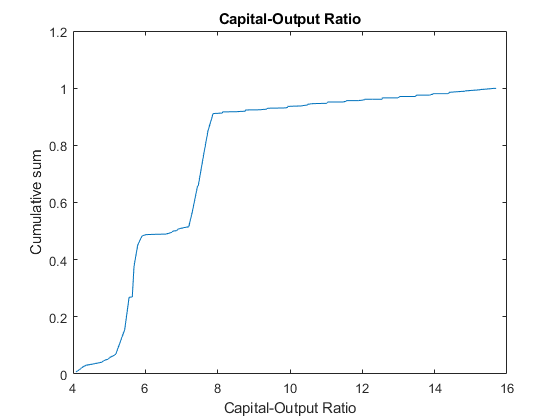

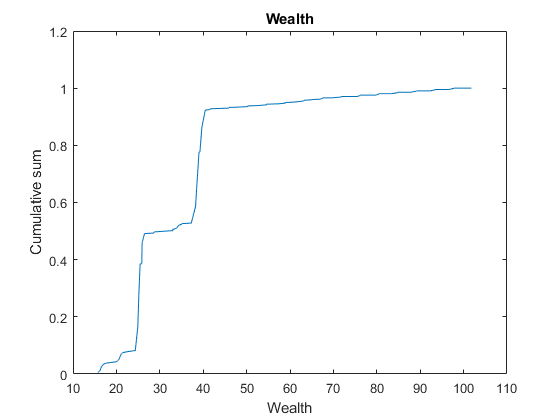


eco_param.alpha = 0.4;
eco_param.beta = 0.96;
eco_param.delta = 0.08;
eco_param.gamma = 0.75;

eco_param.sigma_c = 2;
eco_param.sigma_l = 2;

eco_param.tau_n = 0.25;
eco_param.tau_y = 0;

% Determina os parametros r e w da economia
eco_param.r_UpperBound = 1/eco_param.beta -1;
eco_param.r_LowerBond = -eco_param.delta;
eco_param.r = (eco_param.r_UpperBound + eco_param.r_LowerBond)/2;
eco_param.r_tilda = eco_param.r + eco_param.delta;


% Determina os Grids
WageShocks.Values = exp(mkv.StateVector);
WageShocks.Grid.Min = min(WageShocks.Values);
WageShocks.Grid.Max = max(WageShocks.Values);
WageShocks.Grid.N = mkv.QtdStates;
WageShocks.PI = mkv.TransitionMatrix;

% Determina as caracteristicas do grid de trabalho
Labor.Grid.N = 20;
Labor.Grid.Min = 0.01;
Labor.Grid.Max = 1;
Labor.Values = linspace(Labor.Grid.Min, Labor.Grid.Max, Labor.Grid.N);

G0 = CalculaRendaGov(eco_param.tau_y ,Labor, WageShocks, eco_param, 1);


eco_param.tau_n = 0.20

eco_param = struct with fields:
           alpha: 0.4000
            beta: 0.9600
           delta: 0.0800
           gamma: 0.7500
         sigma_c: 2
         sigma_l: 2
           tau_n: 0.2000
           tau_y: 0
    r_UpperBound: 0.0417
     r_LowerBond: -0.0800
               r: -0.0192
         r_tilda: 0.0608


f = @(tau_y)( G0 - CalculaRendaGov(tau_y, Labor, WageShocks, eco_param, 0));

sol = fsolve(f,0.024);

tau_y:0.024	tau_n:0.200
tau_y:0.024	tau_n:0.200
tau_y:0.023	tau_n:0.200
tau_y:0.023	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200
tau_y:0.021	tau_n:0.200

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradien

tau_y:0.021	tau_n:0.200
Inter:   1	r: -0.019167	Dem: -9.573394
Inter:   2	r: -0.049583	Dem: 58.723891
Inter:   3	r: -0.034375	Dem: 17.357920
Inter:   4	r: -0.026771	Dem: 5.390330
Inter:   5	r: -0.022969	Dem: -0.160819
Inter:   6	r: -0.024870	Dem: 2.792012
Inter:   7	r: -0.023919	Dem: 1.075791
Inter:   8	r: -0.023444	Dem: 0.473222
Inter:   9	r: -0.023206	Dem: 0.150688
Inter:  10	r: -0.023088	Dem: -0.004259
Inter:  11	r: -0.023147	Dem: 0.078635
Inter:  12	r: -0.023117	Dem: 0.034880
Inter:  13	r: -0.023102	Dem: 0.015311
Inter:  14	r: -0.023095	Dem: 0.005526
Inter:  15	r: -0.023091	Dem: 0.000633
Inter:  16	r: -0.023089	Dem: -0.001813
Inter:  17	r: -0.023090	Dem: -0.000590
Inter:  18	r: -0.023091	Dem: 0.000022
Inter:  19	r: -0.023091	Dem: -0.000284
Inter:  20	r: -0.023091	Dem: -0.000131
Inter:  21	r: -0.023091	Dem: -0.000055
Inter:  22	r: -0.023091	Dem: -0.000016
interest rate: -0.023091
wage rate: 1.769679


ans = 20×7 table
     Var1      Var2      Var3      Var4      Var5      Var6      Var7 
    ______    ______    ______    ______    ______    ______    ______

       100    15.848    15.848    15.848    15.848    15.848    20.277
    15.848    20.277    20.277    20.277    20.277    20.277    24.706
    20.277    24.706    24.706    24.706    24.706    24.706    29.135
    24.706    24.706    29.135    24.706    24.706    29.135    33.564
    29.135    29.135    33.564    33.564    33.564    33.564    37.993
    33.564    33.564    37.993    37.993    37.993    37.993    37.993
    37.993    37.993    37.993    37.993    37.993    37.993    37.993
    42.422    42.422    42.422    46.851    46.851    42.422    42.422
    46.851    46.851    46.851    

ans = 20×7 table
    Var1     Var2       Var3       Var4       Var5       Var6       Var7  
    ____    _______    _______    _______    _______    _______    _______

    0.01    0.84368    0.68737    0.58316    0.47895    0.37474    0.68737
    0.01    0.89579    0.73947    0.58316    0.47895    0.42684    0.68737
    0.01    0.94789    0.79158    0.63526    0.53105    0.42684    0.68737
    0.01       0.01    0.84368       0.01       0.01    0.42684    0.68737
    0.01       0.01    0.89579    0.68737    0.53105    0.42684    0.73947
    0.01       0.01    0.94789    0.73947    0.58316    0.47895    0.37474
    0.01       0.01       0.01       0.01       0.01       0.01       0.01
    0.01       0.01       0.01    0.79158    0.63526       0.01      

ans = 20×7 table
     Lambda1      Lambda2      Lambda3       Lambda4       Lambda5       Lambda6       Lambda7  
    _________    _________    __________    __________    __________    __________    __________

    0.0048275    0.0073525     0.0090101     0.0085093     0.0058144     0.0024458    8.6144e-05
    0.0049136    0.0075242       0.00927     0.0088076     0.0060743     0.0026176    0.00017229
    0.0049997     0.083461       0.11006       0.10712      0.074169      0.031348     0.0012643
    0.0020709    0.0038253     0.0025777    0.00013897    5.6511e-05     0.0009166     0.0012078
    0.0020774    0.0039578     0.0055569     0.0059898     0.0048784     0.0029277      0.001226
     0.002084    0.0039695      0.053198      0.089202       0.10

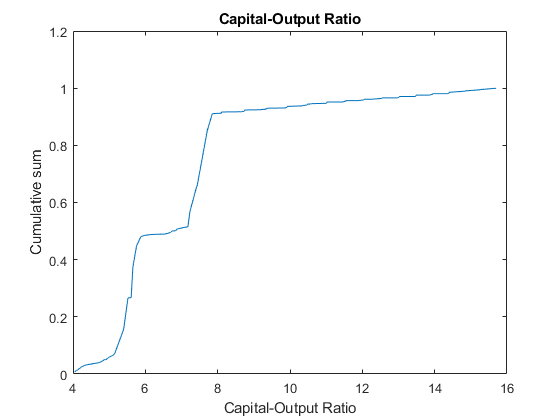

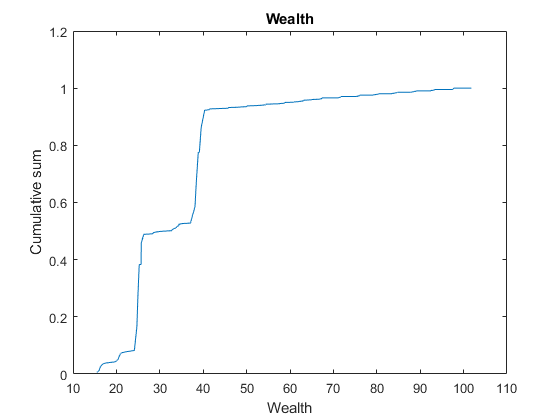


CalculaRendaGov(sol, Labor, WageShocks, eco_param, 1);